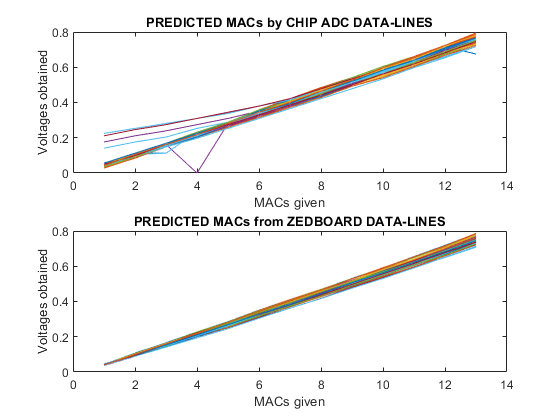

clear;clc;
addpath("D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\lowerLevelCode\FPGA_COMMUNICATE");
addpath("D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\lowerLevelCode\FPGA_CONTROL");
addpath("D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\lowerLevelCode\MISC");
addpath("D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\lowerLevelCode\POWER_SUPPLY_CONTROL");

load('basic_1XHybridMode_analyse_10-Aug-2023_12_12_29.mat');
%load('basic_1XHybridMode_analyse_10-Aug-2023_12_21_20.mat');

ADC_predicted=[];
for iter=1:size(ADC_SC_collect,1)
    a=reshape(ADC_SC_collect(iter,:),[],92);b=2.^[0,1,2,3,4,5,6]';c=b'*a;ADC_predicted=[ADC_predicted;c];
end
ADC_predicted_volts=(ADC_predicted/(2^7))*0.9;

ZEDBOARD_ADC=reshape(adc_VPVN,88,[]);ZEDBOARD_ADC=ZEDBOARD_ADC';
ZEDBOARD_ADC_Ref=reshape(adc_AUX00,88,[]);ZEDBOARD_ADC_Ref=ZEDBOARD_ADC_Ref';

numOnesRefArray=[142:-4:105];
numOnesData_DL_array=147;
xdata=(numOnesData_DL_array-numOnesRefArray)*4;
xdata=xdata';
xdata=repmat(xdata,1,92);

DL_indices=[1:18,27:62,71:88];
RL_indices=[19:26,63:70];

figure;
subplot(2,1,1)
plot(ADC_predicted_volts(:,DL_indices+2));
title('PREDICTED MACs by CHIP ADC DATA-LINES');
xlabel('MACs given');
ylabel('Voltages obtained');
hold on;

subplot(2,1,2)
plot(ZEDBOARD_ADC(:,DL_indices));
title('PREDICTED MACs from ZEDBOARD DATA-LINES');
xlabel('MACs given');
ylabel('Voltages obtained');

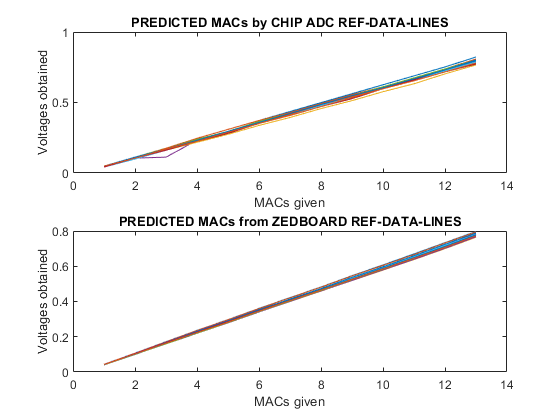



figure;
subplot(2,1,1)
plot(ADC_predicted_volts(:,RL_indices+2));
title('PREDICTED MACs by CHIP ADC REF-DATA-LINES');
xlabel('MACs given');
ylabel('Voltages obtained');
hold on;
subplot(2,1,2)
plot(ZEDBOARD_ADC_Ref(:,RL_indices));
title('PREDICTED MACs from ZEDBOARD REF-DATA-LINES');
xlabel('MACs given');
ylabel('Voltages obtained');